Per prima cosa definiamo quante sono le coordinate generalizzate del robot:

n=3 

n = 3

**Ricordiamo che il tutto viene calcolato rispetto all' origine del frame definito da 1 in poi**

Poi dobbiamo definire tutte le variabili simboliche di nostro utilizzo:

q = sym('q', [n, 1]);
for i=1:n
    nomeVariabile = ['q' num2str(i)];
    assignin('base', nomeVariabile,q(i,1));
end

L = sym('l', [n, 1]);
for i=1:n
    nomeVariabile = ['l' num2str(i)];
    assignin('base', nomeVariabile,L(i,1));
end

%inertia matrix for each link
I = sym('Ic', [3, 3, n]);
for i=1:n
    I(1,1,i)=sym(['Ic' num2str(i) 'xx']);I(1,2,i)=sym(['Ic' num2str(i) 'xy']); I(1,3,i)=sym(['Ic' num2str(i) 'xz']);
    I(2,1,i)=sym(['Ic' num2str(i) 'yx']);I(2,2,i)=sym(['Ic' num2str(i) 'yy']); I(2,3,i)=sym(['Ic' num2str(i) 'yz']);
    I(3,1,i)=sym(['Ic' num2str(i) 'zx']);I(3,2,i)=sym(['Ic' num2str(i) 'zy']); I(3,3,i)=sym(['Ic' num2str(i) 'zz']);
end

m = sym('m', [n, 1]);
for i=1:n
    nomeVariabile = ['m' num2str(i)];
    assignin('base', nomeVariabile,m(i,1));
end

pcx = sym('pcx', [1,n]);
for i=1:n
    nomeVariabile = ['pcx' num2str(i)];
    assignin('base', nomeVariabile,pcx(1,i));
end
pcy = sym('pcy', [1,n]);
for i=1:n
    nomeVariabile = ['pcy' num2str(i)];
    assignin('base', nomeVariabile,pcy(1,i));
end
pcz = sym('pcz', [1,n]);
for i=1:n
    nomeVariabile = ['pcz' num2str(i)];
    assignin('base', nomeVariabile,pcz(1,i));
end

pcz=subs(pcz,pcz,zeros(1,n));  % da cancellare se si vogliono fare calcoli con pcz 
% DA CANCELLARE SE SONO IN 3D, DA LASCUARE SE SONO IN 2D

uni=ones(1,n);
com=[pcx;pcy;pcz;uni]

$$com = \left(\begin{array}{ccc} {\mathrm{pcx}}_{1} & {\mathrm{pcx}}_{2} & {\mathrm{pcx}}_{3}\\ {\mathrm{pcy}}_{1} & {\mathrm{pcy}}_{2} & {\mathrm{pcy}}_{3}\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

Adesso dobbiamo notare che molto spesso ci sono delle condizioni che semplificano la posizione del centro di massa.

**When the center of mass is located on the kinematics axis of the links **we can introduce other variables in order to characterize well the position of the center of mass. 

D = sym('dc', [n, 1]);
for i=1:n
    nomeVariabile = ['dc' num2str(i)];
    assignin('base', nomeVariabile,D(i,1));
end

Queste distanze vanno dal joint_i al CoM del link i. Quindi per capirci, Il joint 1 è quello alla base del robot, e il link 1 è il primo, quello che connette il joint alla base con il joint 2. dc1 è la distanza fra il joint1 e il centro di massa e cosi via.

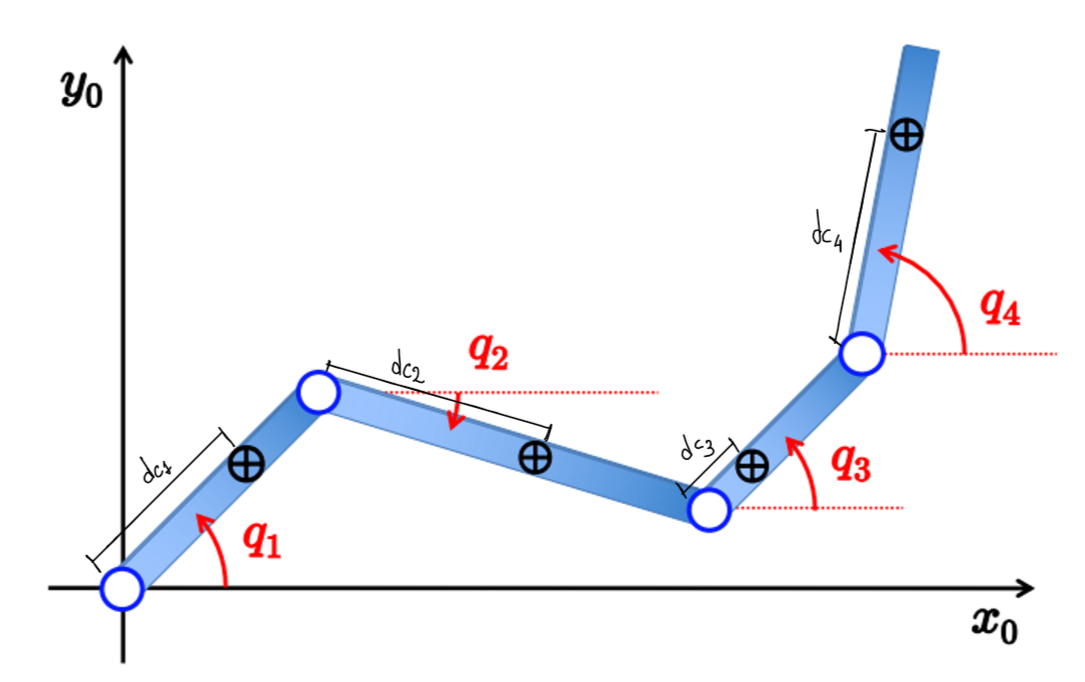

**Corretta assegnazione delle variabili simboliche rispetto il nostro esercizio ( a mano ) **

Purtroppo come assegnare i parametri dc alle variabili del vettore com **va fatto a mano,** perche ci sono troppe complicazioni nel farlo in matlab e si rischia di sbagliare.

Nota che lo script è settato per utilizzare tutti i parametri possibili e inimmaginabili, se in un determinato esercizio trovi scritto 

devi usare solamente i parametri presenti nella figura. **Generalmente per un revolut joint abbiamo tutte le info **, mentre per un **joint prismatic if we do not have information abount the center of mass we have to consider directly the kinetic energy of the joint not considering the center of mass. CIOè SE HAI UN PROSMATIC E NON HAI INFO SULLA POSIZIONE DEL CENTRO DI MASSA CONSIDERI LA VARIABILE DI GIUNTO **

**POSIZIONI DEI CENTRI DI MASSA RISPETTO L' ORIGINE DEL FRAME 0 o WOLRD FRAME.**

in questo esercizio non sono state date ne le lunghezze dei link1 e link2 e neanche le posizioni dei centri di massa rispetto ai link 

%Se non hai info sul centro di massa (prismatic joint) consideri la
%variabile di giunto 

%assegnazioni rispetto i lframe di base
%assegnamo la prima posizione del centro di massa: 
com(1,1)=0;   %pcx1
com(2,1)=q1;     %pcy1      
com(3,1)=0;                 %pcz1         %era zero e rimane zero 

%assegnamo la seconda posizione del centro di massa:   
com(1,2)=dc2*cos(q2);   %pcx2
com(2,2)=q1+dc2*sin(q2);    %pcy2      
com(3,2)=0;                           %pcz2         %era zero e rimane zero 


%assegnamo la terza posizione del centro di massa:
com(1,3)=l2*cos(q2);      %pcx3
com(2,3)=q1+l2*sin(q2);       %pcy3
com(3,3)=0;                                         %pcz3       %era zero e rimane zero 

%assegnamo la quarta posizione del centro di massa:
%com(1,4)=l1*(cos(q1))+l2*cos(q2)+l3*cos(q3)+dc4*cos(q4);        %pcx4
%com(2,4)=l1*(sin(q1))+l2*sin(q2)+l3*sin(q3)+dc4*sin(q4);        %pcy4
%com(3,4)=0;                                                     %pcz4       %era zero e rimane zero 

com

$$com = \left(\begin{array}{ccc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right) & l_{2}\,\cos\left(q_{2}\right)\\ q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right) & q_{1}+l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

**Configurazione delle matrici di inerzia:**

- **Joint rotazionali, nessuna modifica, lasciala cosi numerica**

- **joint prismatici:**

**                - Se non è preceduto da nessun Joint rotazionale allora impostare la sua matrice di inerzia =0**

**                - Se è preceduto da un joint rotazionale lasicala cosi numerica**

                    ricordando che il contirbuto rotazionale all' energia cinetica di questo joint prismatico è dattato dalla velocità                     

                    angolare del/dei joint rotazionali precedenti ad esso    

I(:,:,1)=zeros(n,n); % se il primo joint è prismatico 
I

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} \mathrm{Ic2xx} & \mathrm{Ic2xy} & \mathrm{Ic2xz}\\ \mathrm{Ic2yx} & \mathrm{Ic2yy} & \mathrm{Ic2yz}\\ \mathrm{Ic2zx} & \mathrm{Ic2zy} & \mathrm{Ic2zz} \end{array}\right)$$

$$\left(\begin{array}{ccc} \mathrm{Ic3xx} & \mathrm{Ic3xy} & \mathrm{Ic3xz}\\ \mathrm{Ic3yx} & \mathrm{Ic3yy} & \mathrm{Ic3yz}\\ \mathrm{Ic3zx} & \mathrm{Ic3zy} & \mathrm{Ic3zz} \end{array}\right)$$

Ora che abbiamo tutte le posizioni procediamo con il **calcolo dell' energia cinetica**. Qui non possiamo usare i moving frames in quanto non abbiamo la notazione con D-H, **NECESSARIA PER I MOVING FRAMES**

%components of kinetic energy:
t = sym('T', [n,1]);
qd = sym('qd', [n, 1]);
for i=1:n
    nomeVariabile = ['qd' num2str(i)];
    assignin('base', nomeVariabile,qd(i,1));
end

Ricorda che:


$$T_i=\frac{1}{2}m_i \ v_{cm_i}^T \ v_{cm_i}\ + \ \frac{1}{2}\omega_i^T \ I_{cm_i} \ \omega_i$$


nota che se non hai info su posizioni del centro di massa(primsatic Joint) sei interessato all' energia potenziale del joint e non del centro di massa. quindi se il primo joint è prismatico la velocità è semplicemente $\dot{q_1}$ che è sempre un vettore con direzione in base a com'è posizionato il joint rispetto il riferimento di base.

**dove per calcolare **$\mathbf{V_{cm_i}}$** devo tenere in considerazione del contributo fornito dai joint precedenti al joint i.**

** mentre per calcolare **$\mathbf{\omega_i}$** ho due scenari:**

- **joint i rotazionale -> si considera la velocità angolare ****data dalla sua rotazione**

- **Joint prismatico -> si considera la velocità angolare di TUTTI joint rotazionali CHE LO PRECEDNONO.**

**quindi questa ambiguità nel definire la velocità angolare per ogni joint porta ad una configurazione manuale:**

%ricordati che il contributo va messo rispetto l' asse in cui avviene la
%rotazione , se asse Z -> contributo in terza posizione
omega_cm1=[0;0;0];
omega_cm2=[0;0;qd2];
omega_cm3=[0;0;qd3];
%omega_cm4=[];
omega=[omega_cm1,omega_cm2,omega_cm3];
%omega=[omega_cm1,omega_cm2,omega_cm3,omega_cm4];
if(size(omega)~=n)
    error('Hai sbagliato a inserire le velocità angolari, ne manca qualcuna');
end

**Calcolo energia cinetica**

%calcolo di T1, dove omega è stata inserita a mano perche non posso capire
%a priori che direzione ha

pcm1=[com(1,1);com(2,1);com(3,1)] %pcx1;pcy1;pcz1

$$pcm1 = \left(\begin{array}{c} 0\\ q_{1}\\ 0 \end{array}\right)$$

vcm1=diff(pcm1,q1)*qd1

$$vcm1 = \left(\begin{array}{c} 0\\ {\mathrm{qd}}_{1}\\ 0 \end{array}\right)$$

trasl_partT1=1/2*m1*simplify(transpose(vcm1)*vcm1)

$$trasl\_partT1 = \frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

omega_cm1

omega_cm1 =      0
     0
     0


rot_partT1=1/2*transpose(omega_cm1)*I(:,:,1)*omega_cm1

$$rot\_partT1 = 0$$

t(1,1)=simplify(rot_partT1+trasl_partT1); %T1
T1=t(1,1)

$$T1 = \frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

%calcolo di T2
pcm2=[com(1,2);com(2,2);com(3,2)] %pcx2;pcy2;pcz2

$$pcm2 = \left(\begin{array}{c} {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

vcm2=diff(pcm2,q1)*qd1+diff(pcm2,q2)*qd2

$$vcm2 = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{qd}}_{1}+{\mathrm{dc}}_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$

trasl_partT2=1/2*m2*simplify(transpose(vcm2)*vcm2)

$$trasl\_partT2 = \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}\right)}{2}$$

omega_cm2

$$omega\_cm2 = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{qd}}_{2} \end{array}\right)$$

rot_partT2=1/2*transpose(omega_cm2)*I(:,:,2)*omega_cm2

$$rot\_partT2 = \frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{2}}^{2}}{2}$$

t(2,1)=simplify(rot_partT2+trasl_partT2); %T2
T2=t(2,1)

$$T2 = \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{2}}^{2}}{2}$$

%calcolo di T3
pcm3=[com(1,3);com(2,3);com(3,3)] %pcx3;pcy3;pcz3

$$pcm3 = \left(\begin{array}{c} l_{2}\,\cos\left(q_{2}\right)\\ q_{1}+l_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

vcm3=diff(pcm3,q1)*qd1+diff(pcm3,q2)*qd2+diff(pcm3,q3)*qd3

$$vcm3 = \left(\begin{array}{c} -l_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{qd}}_{1}+l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$

trasl_partT3=1/2*m3*simplify(transpose(vcm3)*vcm3)

$$trasl\_partT3 = \frac{m_{3}\,\left({l_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,l_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}\right)}{2}$$

omega_cm3

$$omega\_cm3 = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{qd}}_{3} \end{array}\right)$$

rot_partT3=1/2*transpose(omega_cm3)*I(:,:,3)*omega_cm3

$$rot\_partT3 = \frac{\mathrm{Ic3zz}\,{{\mathrm{qd}}_{3}}^{2}}{2}$$

%t(3,1)=simplify(expand(rot_partT3+trasl_partT3)); %T3
t(3,1)=simplify((rot_partT3+trasl_partT3)); %T3
T3=t(3,1)

$$T3 = \frac{\mathrm{Ic3zz}\,{{\mathrm{qd}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({l_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,l_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}\right)}{2}$$

%calcolo di T4
%pcm4=[com(1,4);com(2,4);com(3,4)] %pcx4;pcy4;pcz4
%vcm4=diff(pcm4,q1)*qd1+diff(pcm4,q2)*qd2+diff(pcm4,q3)*qd3+diff(pcm4,q4)*qd4
%trasl_partT4=1/2*m4*simplify(transpose(vcm4)*vcm4)
%omega_cm4
%rot_partT4=1/2*transpose(omega_cm4)*I(:,:,2)*omega_cm4
%t(4,1)=simplify(rot_partT4+trasl_partT4); %T4
%T4=t(4,1)

Calcolo dell' energia cinetica in modo iterativo 

% for i=1:n
%     disp(' ');
%     disp('------------------------------------------')
%     disp(["Componente dell'energia cinetica" num2str(i) ])
%     pcm=[com(1,i);com(2,i);com(3,i)]
%     Vcm=0;
%     for j=1:i
%        Vcm=simplify(Vcm+diff(pcm,q(j,1))*qd(j,1));
%     end
%     Vcm
%     trasl_part=simplify(1/2*m(i,1)*transpose(Vcm)*Vcm)
% 
%     omega=omegas(:,:,i)
%     rot_part=simplify(1/2*transpose(omega)*I(:,:,i)*omega )
% 
%     Ti=simplify(trasl_part+rot_part)
%     t(i,1)=Ti;
%     disp(' ');disp(' ');
% end

Energia Cinetica Totale

%Calcolo di T -> energia cinetica totale
T=T1;
for i=2:n
    T=T+t(i,1);
end
T=simplify(T)

$$T = \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{\mathrm{Ic3zz}\,{{\mathrm{qd}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({l_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,l_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}\right)}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

%simplify(expand(T3))

Adesso dobbiamo ricavare la matrice M:


$$T(q)=\dot{q}^T M(q)\dot{q}$$


M(1,1)=simplify(diff(T,qd1,2));
M(2,2)=simplify(diff(T,qd2,2));
M(3,3)=simplify(diff(T,qd3,2));
%M(4,4)=simplify(diff(T,qd4,2));
M(2,1)=simplify(diff(diff(T,qd1),qd2));
M(3,1)=simplify(diff(diff(T,qd1),qd3));
%M(4,1)=simplify(diff(diff(T,qd1),qd4));
M(3,2)=simplify(diff(diff(T,qd2),qd3));
%M(4,2)=simplify(diff(diff(T,qd2),qd4));
%M(4,3)=simplify(diff(diff(T,qd3),qd4));

%M è simmetrica quindi:
M(1,2)=M(2,1);
M(1,3)=M(3,1);
%M(1,4)=M(4,1);
M(2,3)=M(3,2);
%M(2,4)=M(4,2);
%M(3,4)=M(4,3);

M

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & \cos\left(q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right) & 0\\ \cos\left(q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{l_{2}}^{2}+\mathrm{Ic2zz} & 0\\ 0 & 0 & \mathrm{Ic3zz} \end{array}\right)$$